# section 1

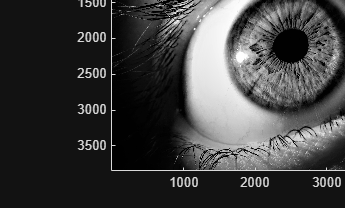

img = imread('test1b.jpg');
img = im2double(img);

figure;
imagesc(img);
colormap(gray);
axis image;
title('Original Image');

## section 2

pixels = round(img * 255) + 1;

H = histcounts(pixels, 1:257);

C = cumsum(H);

H0 = H(find(H > 0, 1));

mapping = (C - H0) / (numel(img) - H0);

mapping = max(0, mapping);

eq_img = reshape(mapping(pixels), size(img));


## section 3

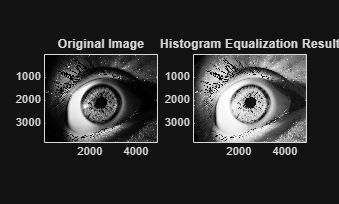

figure;
subplot(1,2,1);
imagesc(img);
caxis([0 1]);
title('Original Image');
axis equal tight;

subplot(1,2,2);
imagesc(eq_img);
caxis([0 1]);
title('Histogram Equalization Result');
axis equal tight;
colormap(gray);

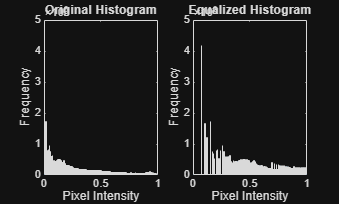


figure;
subplot(1,2,1);
histogram(img(:), 256, 'BinLimits', [0 1]);
title('Original Histogram');
xlabel('Pixel Intensity');
ylabel('Frequency');
xlim([0 1]);

subplot(1,2,2);
histogram(eq_img(:), 256, 'BinLimits', [0 1]);
title('Equalized Histogram');
xlabel('Pixel Intensity');
ylabel('Frequency');
xlim([0 1]);


fprintf(1,'Min/max of input image: %3.3f %3.3f\n', min(img(:)), max(img(:)));

Min/max of input image: 0.000 1.000


fprintf(1,'Min/max of output image: %3.3f %3.3f\n', min(eq_img(:)), max(eq_img(:)));

Min/max of output image: 0.000 1.000
